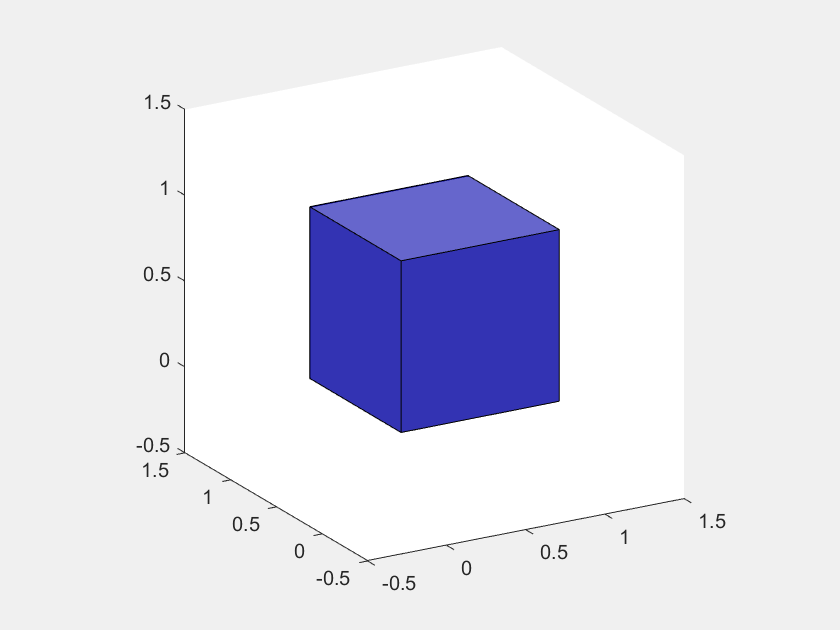

close all 
clear

f = figure("Visible","on");

c = [0 0 0.5; 0.4 0.4 0.8; 0.2 0.2 0.7; 0 0 0.5; 0.2 0.2 0.7; 0 0 0.5];
[vertices,faces,normals] = cubeValues();
for k = 1:6
    patch("Vertices",vertices,"Faces",faces(k,:),...
          "FaceColor","Flat","FaceVertexCData",c(k,:),"FaceAlpha",1,...
          "ButtonDownFcn",{@clickCallback,normals(k,:)/2});
end
axis equal
view(-30,20)
axis([-1,1,-1,1,-1,1]*1 + 0.5)


disableDefaultInteractivity(gca)

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function clickCallback(src,evt,n) %#ok<*INUSL> 
    p = evt.IntersectionPoint;
    hold on
    quiver3(p(1),p(2),p(3),n(1),n(2),n(3),"linewidth",1,...
        "Autoscale","off","MaxHeadSize",0.3,"Color",[0 0 0])
    hold off
end

